close all;
clear all;

%Carga de imagenes
%Cambiar el nombre segun la imagen a analizar
titulo_img = 'haz_angosto_300mm.jpg';%Lo uso para cargar la imagen
titulo_img_graf = 'haz ancho 300mm';%Lo uso de titulo de figura
titulo_img_fig = 'haz_ancho_300'; %Lo uso para el nombre al exportar la figura
%titulo_img_fig_config = 'libre'; %es para el nombre al exportar
titulo_img_fig_config = 'ancho';
%titulo_img_fig_config = 'angosto';

k=1; %iteraciones para buscar el maximo matricial promedio
% Si el centro da mal a ojo, aumentar k 

imagen = im2double(rgb2gray(imread(titulo_img)));
imagen_aux = imagen; %el auxiliar lo necesito para buscar el centro
%imagen_aux = imagen_aux./max(imagen_aux); %normalizo para dsps ver umbrales

[fil , col] = size (imagen);

%Esto es para buscar el centro. 
%Busco los primeros K maximos en x e y
%Trabajo sobre una variable auxiliar

for i=1:k
    [Max(i),Ind(i)] = max(imagen_aux(:)); 
    [Ind_fila(i), Ind_col(i)] = ind2sub(size(imagen_aux),Ind(i)); %ind2sub pasa de Ind anterior a los indices fila y columna
    imagen_aux(Ind_fila(i),Ind_col(i))=0; %al maximo encontrado lo borro 
end

%el centro va a estar en los pixels:
fila_max = round( mean(Ind_fila) );

fila_max = 178

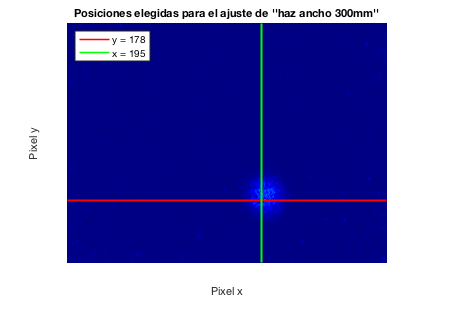

col_max = round( mean(Ind_col) );

%grafico la imagen en falso color y los pixeles 
%xfijo yfijo donde se hara el ajuste
figure();
imshow(gray2ind(imagen), jet());
hold on;
plot(1:(col), fila_max*ones(1,col), "-r", "linewidth", 1.5);
plot(col_max*ones(1,fil), 1:(fil), "-g", "linewidth", 1.5);
title(sprintf('Posiciones elegidas para el ajuste de ''''%s''''',titulo_img_graf));
xlabel('Pixel x');
ylabel('Pixel y');
legend(sprintf('y = %d',fila_max),sprintf('x = %d',col_max),'location','northwest','Fontsize',10);

%print(sprintf('fig_%s_posiciones',titulo_img_fig),'-dpng');

%Para ajustar en el pixel y=cte
med_y = imagen(fila_max,:);
x_0 = 0 : col-1;
x_0 = x_0 - col_max; %le saco la media
%Para ajustar en el pixel x=cte
med_x = transpose( imagen(:,col_max));
y_0 = 0 : fil-1;
y_0 = y_0 - fila_max;

%semilla: [I0 , media=0, w aprox 40] 40pixeles = 1mm
start_x = [imagen(fila_max,col_max), 0, 40];
start_y = [imagen(fila_max,col_max), 0, 40];

%Ajustes
g = fittype('I0*exp(-2*((x^2+k^2)/w^2))','independent','x','dependent','y');
%k va a sar chico porque es y_a o x_a [um] 
%En verdad al correr la gaussiana k=0
%en g dice x, pero puede ser x o sino y
fx = fit(x_0.',med_y.',g,'startpoint',start_x);
fy = fit(y_0.',med_x.',g,'startpoint',start_y);

%Nomenclatura: [I0 , k , w] = coeffvalues(f) 
Px = coeffvalues(fx); %Parametros ajustados en x para y=cte

Px =     0.6512         0   21.7980


Py = coeffvalues(fy); %Parametros ajustados en y para x=cte

Py =     0.6493         0   26.9357


%Parametros promedio
I0_prom = (Px(1) + Py(1))/2 

I0_prom = 0.6502

w_prom = (Px(3) + Py(3))/2 

w_prom = 24.3668

%pixel = 25E-6;
%w_prom_metros = w_prom * pixel

%parametros01_x = fminsearch(@(param) err_cuad_gauss(param, [x_0; med_y]), [1, 1])

parametros01_x =    21.7978    0.6512


%parametros01_y = fminsearch(@(param) err_cuad_gauss(param, [y_0; med_x]), [1, 1])

parametros01_y =    26.9356    0.6493


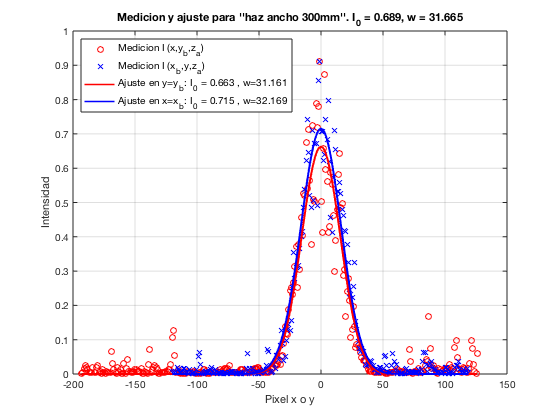



%Grafico los ajustes y mediciones
figure();
plot(x_0,med_y,'ro',"linewidth", 1.3);
hold on;
grid on;
plot(y_0,med_x,'bx',"linewidth", 1.3);
plot(x_0, Px(1)*exp( - 2*((x_0).^2 + Px(2)^2)/ Px(3)^2 ),'-r', 'linewidth',1.5);
plot(y_0, Py(1)*exp( - 2*((y_0).^2 + Py(2)^2)/ Py(3)^2 ),'-b', 'linewidth',1.5);
title(sprintf('Medicion y ajuste para ''''%s''''. I_0 = %.3f, w = %.3f',titulo_img_graf,I0_prom,w_prom));
xlabel('Pixel x o y');
ylabel('Intensidad');
axis([-200 150 0 1]);
legend('Medicion I (x,y_b,z_a)','Medicion I (x_b,y,z_a)',sprintf('Ajuste en y=y_b: I_0 = %.3f , w=%.3f',Px(1),Px(3)),sprintf('Ajuste en x=x_b: I_0 = %.3f , w=%.3f',Py(1),Py(3)),'location','northwest','Fontsize',10);

%print(sprintf('fig_%s_ajuste',titulo_img_fig),'-dpng');
